I =     0.6118    0.6235    0.6196    0.6078    0.6196    0.6118    0.6235    0.6196    0.6157    0.6196    0.6196    0.6235    0.6275    0.6275    0.6275    0.6196    0.6392    0.6314    0.6353    0.6275    0.6431    0.6275    0.6471    0.6392    0.6314    0.6392    0.6314    0.6431    0.6471    0.6353    0.6314    0.6471    0.6471    0.6431    0.6510    0.6471    0.6431    0.6510    0.6549    0.6471    0.6471    0.6431    0.6667    0.6510    0.6549    0.6549    0.6667    0.6588    0.6627    0.6510
    0.6275    0.6039    0.6157    0.6196    0.6157    0.6235    0.6196    0.6196    0.6196    0.6275    0.6078    0.6118    0.6235    0.6196    0.6275    0.6157    0.6471    0.6235    0.6314    0.6196    0.6353    0.6353    0.6314    0.6392    0.6235    0.6353    0.6431    0.6392    0.6431    0.6471    0.6627    0.6431    0.6392    0.6471    0.6314    0.6392    0.6471    0.6588    0.6549    0.6471    0.6431    0.6392    0.6627    0.6627    0.6627    0.6667    0.6667    0.6627    0.6667    0

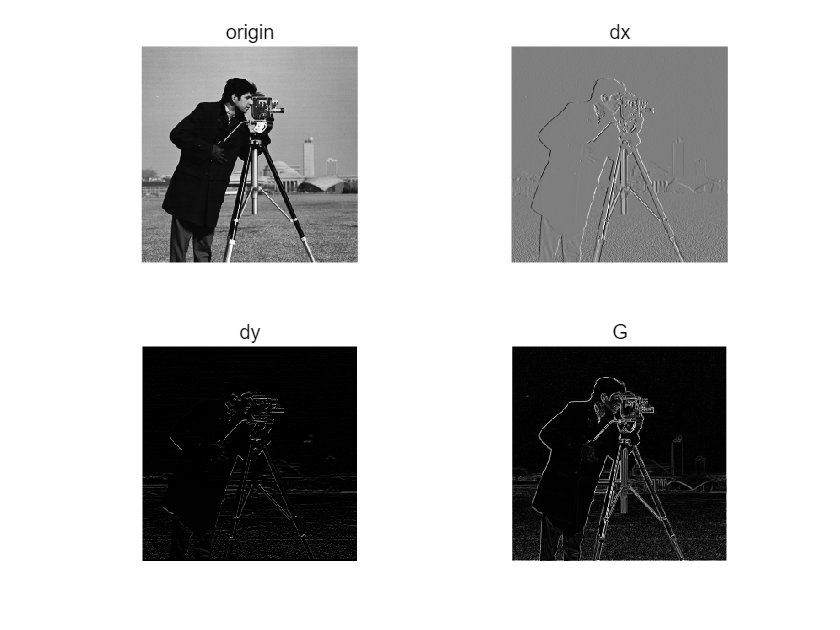

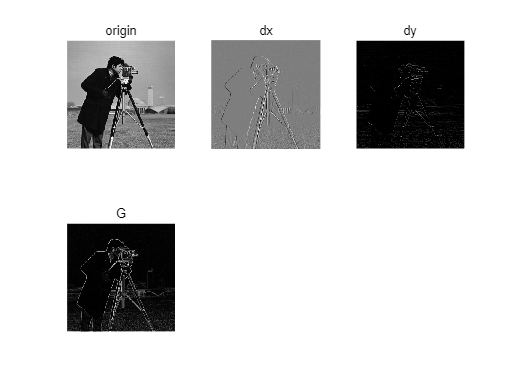

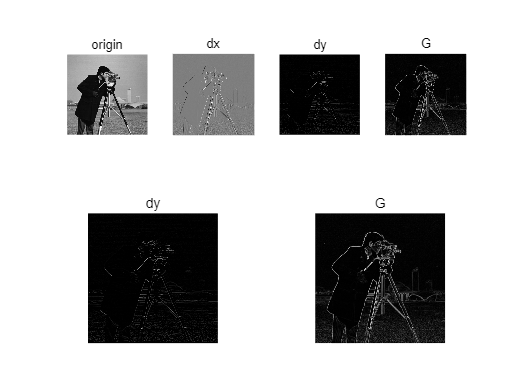

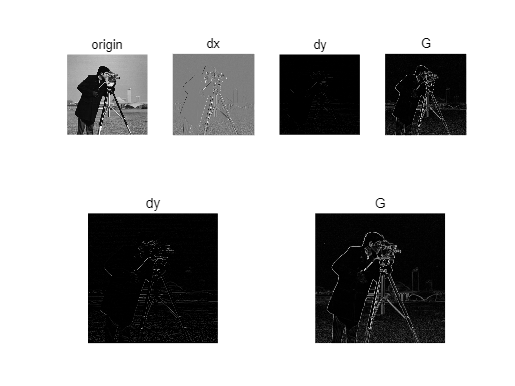

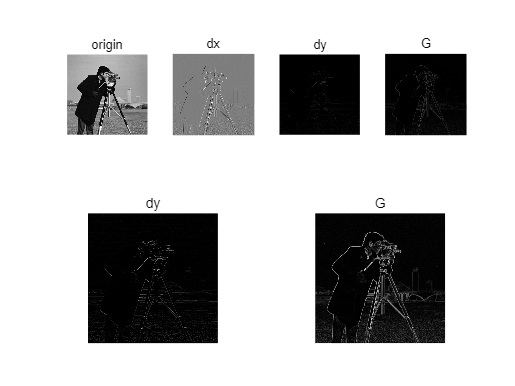

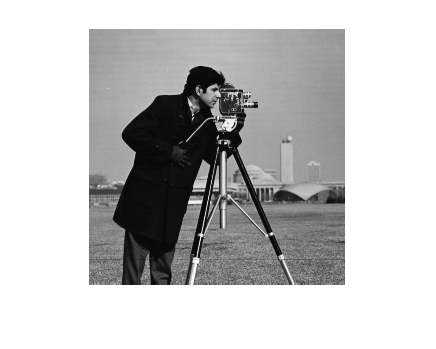

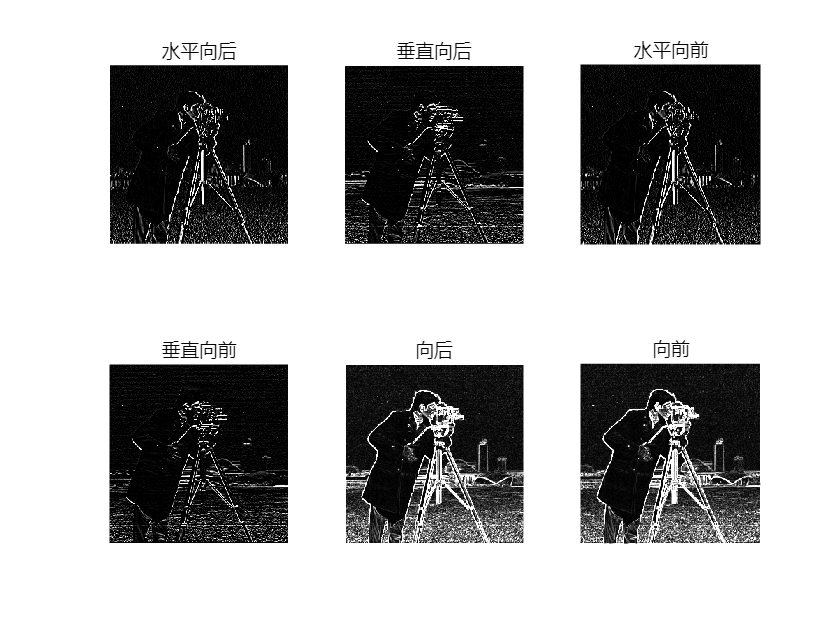

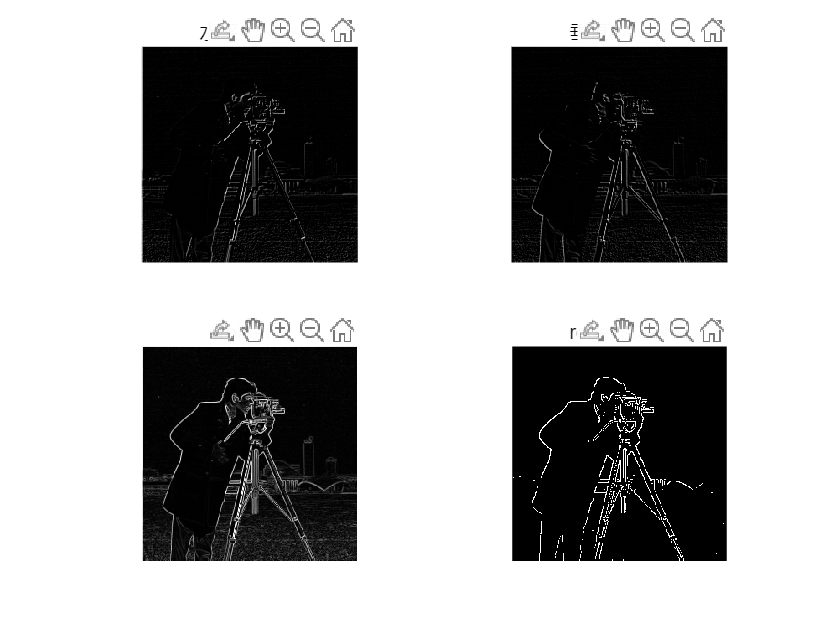

hist_map =     0.0275    0.0001
    0.0314    0.0065
    0.0353    0.0225
    0.0392    0.0192
    0.0431    0.0179
    0.0471    0.0222
    0.0510    0.0233
    0.0549    0.0257
    0.0588    0.0204
    0.0627    0.0148


I = im2double(imread("cameraman.tif"))

%  前向差分二号后向差分？
Wx = [0,0,0;
    0,-1,1;
    0,0,0
    ];
Wy = [0,0,0;
    0,-1,0;
    0, 1, 0
    ];
dx = imfilter(I, Wx);
dy = imfilter(I, Wy);
G = (dx.^2 + dy.^2).^0.5;
figure(),subplot(2,2,1),imshow(I),title("origin");
subplot(2,2,2),imshow(dx, []), title("dx");
% [] 默认为[0,1],matlab中的开窗操作：(x-min_x)/(max_x-min_x)归一化
subplot(2,2,3),imshow(dy),title("dy");
subplot(2,2,4),imshow(G),title("G");

% G是一个反应梯度强度的定量矩阵，但是我们需要的是判断是否为边缘点的二值化矩阵，
% 做一个阈值化操作，认为梯度大于阈值的像素点梯度够大

% 去噪后再差分
H = [0,1,0;
    1,2,1;
    0,1,0];
Wx = [0,0,0;
    0,-1,1;
    0,0,0];
Wy = [0,0,0;
    0,-1,0;
    0, 1, 0];
dx = imfilter(I, Wx);
dy = imfilter(I, Wy);
G = (dx.^2 + dy.^2).^0.5;
figure(),subplot(2,3,1),imshow(I),title("origin");
subplot(2,3,2),imshow(dx, []), title("dx");
% [] 默认为[0,1],matlab中的开窗操作：(x-min_x)/(max_x-min_x)归一化
subplot(2,3,3),imshow(dy),title("dy");
subplot(2,3,4),imshow(G),title("G");

% prewitt梯度算子法，结合了平均和边缘检测，有连续部分的梯度其梯度均值才大，对于去除孤立点更有效
Wx = 1/3 * [0,0,0;
    0,-1,1;
    0,0,0
    ];
Wy = 1/3*[0,0,0;
    0,-1,0;
    0, 1, 0
    ];
dx = imfilter(I, Wx);
dy = imfilter(I, Wy);
G = (dx.^2 + dy.^2).^0.5;
figure(1),subplot(2,4,1),imshow(I),title("origin");
subplot(2,4,2),imshow(dx, []), title("dx");
% [] 默认为[0,1],matlab中的开窗操作：(x-min_x)/(max_x-min_x)归一化
subplot(2,4,3),imshow(dy),title("dy");
subplot(2,4,4),imshow(G),title("G");




% 将读入的图像转化为灰度图
% i = im2double(imread("character.jpg"));
i = im2double(imread("cameraman.tif"));
figure(),imshow(i);

% 正交梯度算子边缘检测（向后差分）
k = 5;
wh = [
    0,0,0;
    -1,1,0;
    0,0,0];
wv = [
    0,-1,0;
    0,1,0;
    0,0,0];
% 正交梯度算子边缘检测（向后差分）
Wx = [0,0,0;
    0,-1,1;
    0,0,0
    ];
Wy = [0,0,0;
    0,-1,0;
    0, 1, 0
    ];
i_h = imfilter(i, k.*wh);
i_v = imfilter(i, k.*wv);
% 梯度合成
i_g = sqrt(i_h.^2 + i_v.^2);
i_h_2 = imfilter(i, k.*Wx);
i_v_2 = imfilter(i, k.*Wy);
% 梯度合成
i_g_2 = sqrt(i_h_2.^2 + i_v_2.^2);
figure(),subplot(2,3,1),imshow(i_h),title("水平向后");
subplot(2,3,2),imshow(i_v),title("垂直向后");
subplot(2,3,3), imshow(i_h_2),title("水平向前");
subplot(2,3,4), imshow(i_v_2),title("垂直向前");
subplot(2,3,5), imshow(i_g),title("向后");
subplot(2,3,6), imshow(i_g_2),title("向前");


% roberts算子边缘检测
wh_roberts = [
    -1,0,0;
    0,1,0;
    0,0,0];
wv_roberts = [
    0,-1,0;
    1,0,0;
    0,0,0];
i_h_roberts = imfilter(i, wh_roberts);
i_v_roberts = imfilter(i, wv_roberts);
% 梯度合成
i_roberts = sqrt(i_h_roberts.^2 + i_v_roberts.^2);
i_roberts_edge = edge(i, "roberts");
figure(),subplot(2,2,1),imshow(i_h_roberts),title("水平roberts");
subplot(2,2,2),imshow(i_v_roberts),title("垂直roberts");
subplot(2,2,3),imshow(i_roberts),title("roberts");
subplot(2,2,4),imshow(i_roberts_edge),title("roberts边缘");



% prewitt算子边缘检测
k = 1/3;
wh_prewitt = [
    -1, 0, 1;
    -1, 0, 1;
    -1, 0, 1];
wv_prewitt = [
    -1, -1, -1;
    0, 0, 0;
    1, 1, 1];
i_h_prewitt = imfilter(i, k*wh_prewitt);
i_v_prewitt = imfilter(i, k*wv_prewitt);
% 梯度合成
i_prewitt = sqrt(i_h_prewitt.^2 + i_v_prewitt.^2);
i_prewitt_edge = edge(i, "prewitt");
figure(),subplot(2,2,1),imshow(i_h_prewitt),title("水平prewitt");
subplot(2,2,2),imshow(i_v_prewitt),title("垂直prewitt");
subplot(2,2,3),imshow(i_prewitt),title("prewitt");
subplot(2,2,4),imshow(i_prewitt_edge),title("prewit边缘");


% sobel算子边缘检测
k = 1/4;
wh_sobel = [
    -1, 0, 1;
    -2, 0, 2;
    -1, 0, 1];
wv_sobel = [
    -1, -2, -1;
    0, 0, 0;
    1, 2, 1];
i_h_sobel = imfilter(i, k*wh_sobel);
i_v_sobel = imfilter(i, k*wv_sobel);
% 梯度合成
i_sobel = sqrt(i_h_sobel.^2 + i_v_sobel.^2);
i_sobel_edge = edge(i, "sobel");
figure(),subplot(2,2,1),imshow(i_h_sobel),title("水平sobel");
subplot(2,2,2),imshow(i_v_sobel),title("垂直sobel");
subplot(2,2,3),imshow(i_sobel),title("sobel");
subplot(2,2,4),imshow(i_sobel_edge),title("sobel边缘");

clear;
i = im2double(imread("cameraman.tif"));
% 使用8方向 kirsch 方向梯度模板检测图像的边缘方向，将结果在同一窗口中显示。
[rows, cols] = size(i);
k = 1/15;
% 东
h_kirsch_1 = [
    -3, -3, 5;
    -3, 0, 5;
    -3, -3, 5];
% 东北
h_kirsch_2 = [
    -3, 5, 5;
    -3, 0, 5;
    -3, -3, -3];
% 北
h_kirsch_3 = [
    5, 5, 5;
    -3, 0, -3;
    -3, -3, -3];
% 西北
h_kirsch_4 = [
    5, 5, -3;
    5, 0, -3;
    -3, -3, -3];
% 西
h_kirsch_5 = [
    5, -3, -3;
    5, 0, -3;
    5, -3, -3];
% 西南
h_kirsch_6 = [
    -3, -3, -3;
    5, 0, -3;
    5, 5, -3];
% 南
h_kirsch_7 = [
    -3, -3, -3;
    -3, 0, -3;
    5, 5, 5];
% 东南
h_kirsch_8 = [
    -3, -3, -3;
    -3, 0, 5;
    -3, 5, 5];

i_kirsch_1 = imfilter(i, k*h_kirsch_1);
i_kirsch_2 = imfilter(i, k*h_kirsch_2);
i_kirsch_3 = imfilter(i, k*h_kirsch_3);
i_kirsch_4 = imfilter(i, k*h_kirsch_4);
i_kirsch_5 = imfilter(i, k*h_kirsch_5);
i_kirsch_6 = imfilter(i, k*h_kirsch_6);
i_kirsch_7 = imfilter(i, k*h_kirsch_7);
i_kirsch_8 = imfilter(i, k*h_kirsch_8);
figure(),subplot(2,4,1),imshow(i_kirsch_1),title("东");
subplot(2,4,2),imshow(i_kirsch_2),title("东北");
subplot(2,4,3),imshow(i_kirsch_3),title("北");
subplot(2,4,4),imshow(i_kirsch_4),title("西北");
subplot(2,4,5),imshow(i_kirsch_5),title("西");
subplot(2,4,6),imshow(i_kirsch_6),title("西南");
subplot(2,4,7),imshow(i_kirsch_7),title("南");
subplot(2,4,8),imshow(i_kirsch_8),title("东南");
% 以最大梯度作为边缘点强度
for r = 1:rows
    for c = 1:cols
        i_kirsch(r, c) = max([i_kirsch_1(r, c), i_kirsch_2(r, c), i_kirsch_3(r, c), i_kirsch_4(r, c), i_kirsch_5(r, c), i_kirsch_6(r, c), i_kirsch_7(r, c), i_kirsch_8(r, c)]);
    end
end
figure(),imshow(i_kirsch),title("kirsch");

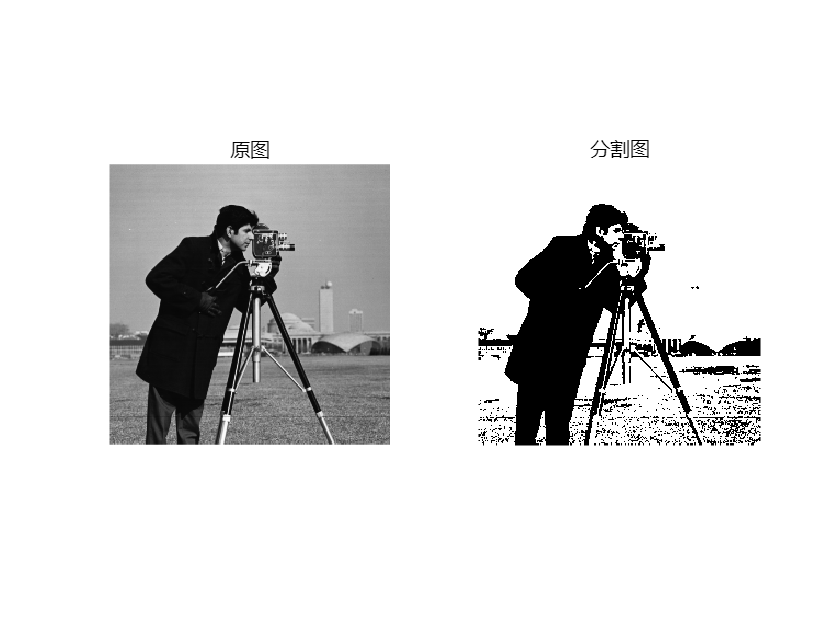

T = 0.5203

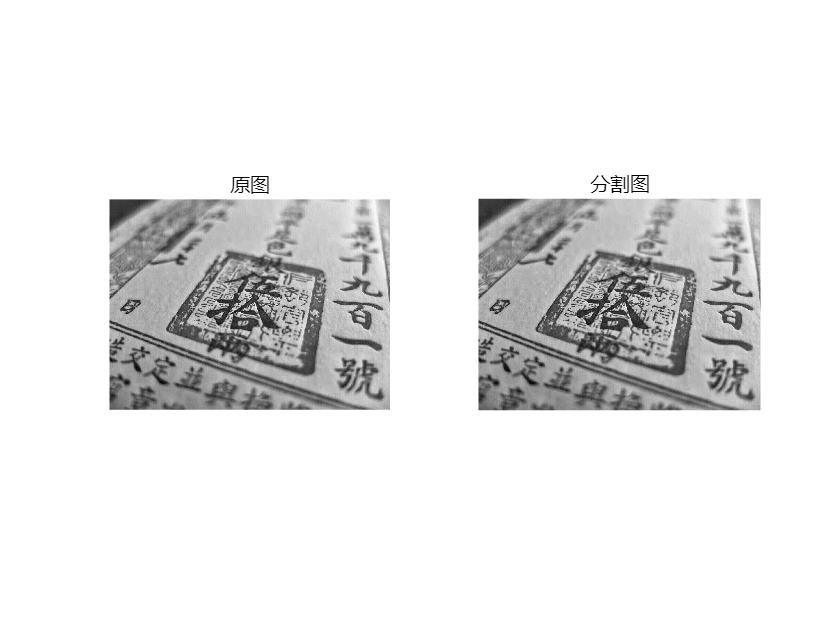

% 获取门限
T = bestT(i);

% 根据阈值对图像进行分割
i_copy = i;
i_copy(i < T) = 0;
i_copy(i >= T) = 1;
figure(),subplot(1,2,1),imshow(i),title("原图");
subplot(1,2,2),imshow(i_copy),title("分割图");